clc; clear; close all;

% Parámetros del sistema
V_pfr = 150; % Volumen del PFR en litros
n = 15; % Número de CSTR en serie
V_cstr = V_pfr / n; % Volumen de cada CSTR

% Constantes de reacción
k = 0.1; % Constante cinética de primer orden

% Flujo de entrada
F_A = 1; % Flujo inicial de A en mol/h
F_B = 1; % Flujo inicial de B en mol/h

% Matrices de estado para n CSTR en serie
A = -k * eye(n);
B = (1/V_cstr) * ones(n,1);
C = ones(1,n); % Ajuste de la salida para compatibilidad
D = 0;

% Crear función de transferencia del sistema
sys = ss(A, B, C, D);
G = tf(sys);

% Mostrar función de transferencia sin control
disp('Función de transferencia sin control:');

Función de transferencia sin control:


G

G =
 
      1.5 s^14 + 2.1 s^13 + 1.365 s^12 + 0.546 s^11 + 0.1502 s^10 + 0.03003 s^9 + 0.004505 s^8 + 0.0005148 s^7 + 4.505e-05 s^6 + 3.003e-06 s^5 + 1.502e-07 s^4 + 5.46e-09 s^3 + 1.365e-10 s^2 + 2.1e-12 s + 1.5e-14
  ----------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^15 + 1.5 s^14 + 1.05 s^13 + 0.455 s^12 + 0.1365 s^11 + 0.03003 s^10 + 0.005005 s^9 + 0.0006435 s^8 + 6.435e-05 s^7 + 5.005e-06 s^6 + 3.003e-07 s^5 + 1.365e-08 s^4 + 4.55e-10 s^3 + 1.05e-11 s^2 + 1.5e-13 s + 1e-15
 
Continuous-time transfer function.


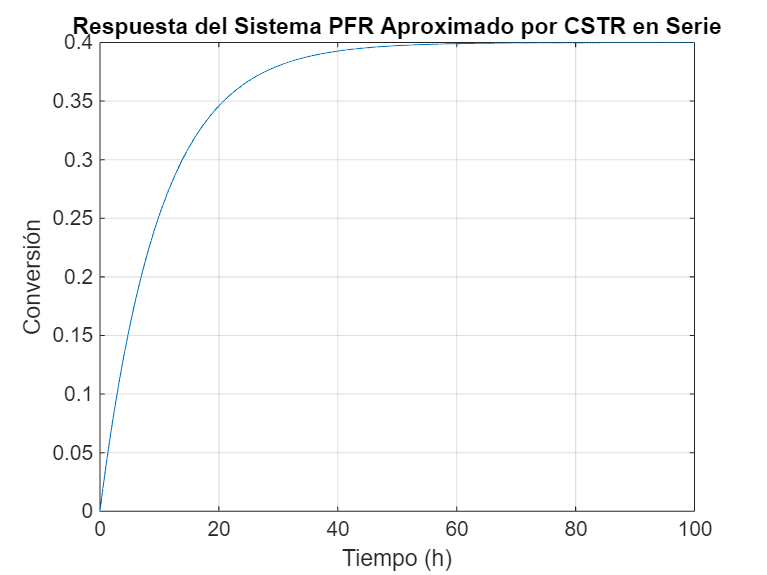


% Representación en el tiempo
t = linspace(0, 100, 1000); % Tiempo en horas
u = ones(size(t)); % Entrada escalón
[y, t_out] = lsim(G, u, t);

% Gráfica de respuesta en el tiempo
figure;
plot(t_out, y/(n*2.5));
xlabel('Tiempo (h)'); ylabel('Conversión');
title('Respuesta del Sistema PFR Aproximado por CSTR en Serie');
grid on;

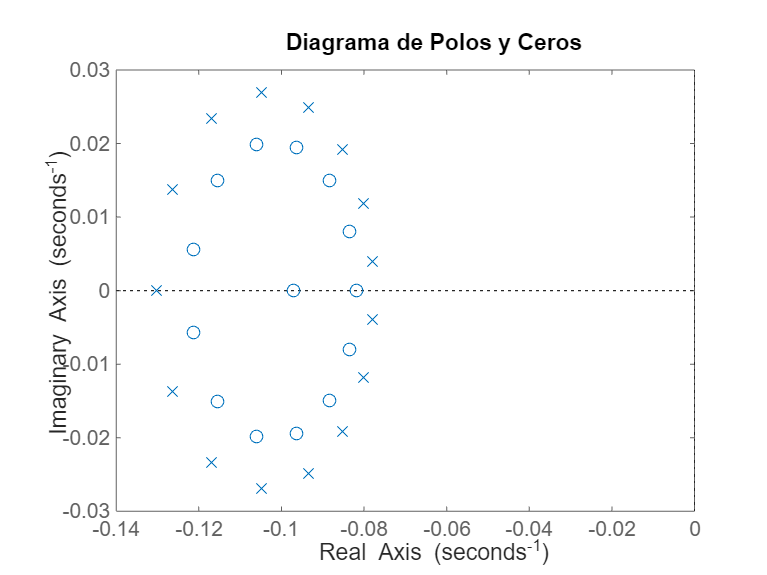


% Diagrama de polos y ceros
figure;
pzmap(G);
title('Diagrama de Polos y Ceros');


% Sintonización del control PID
Kp = 10; Ki = 5; Kd = 0.1; % Ajuste para estabilización en 0.8
PID = pid(Kp, Ki, Kd);
G_PID = feedback(PID * G, 1, -1); % Ajuste para compatibilidad de tamaños

% Mostrar función de transferencia con control PID
disp('Función de transferencia con control PID:');

Función de transferencia con control PID:


G_PID

G_PID =
 
  0.15 s^16 + 15.21 s^15 + 28.64 s^14 + 24.2 s^13 + 12.3 s^12 + 4.235 s^11 + 1.052 s^10 + 0.1952 s^9 + 0.02768 s^8 + 0.003025 s^7 + 0.0002553 s^6 + 1.652e-05 s^5 + 8.054e-07 s^4 + 2.867e-08 s^3 + 7.035e-10 s^2 + 1.065e-11 s + 7.5e-14
  ----------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  1.15 s^16 + 16.71 s^15 + 29.69 s^14 + 24.66 s^13 + 12.44 s^12 + 4.265 s^11 + 1.057 s^10 + 0.1959 s^9 + 0.02774 s^8 + 0.00303 s^7 + 0.0002556 s^6 + 1.653e-05 s^5 + 8.058e-07 s^4 + 2.868e-08 s^3 + 7.037e-10 s^2 + 1.065e-11 s + 7.5e-14
 
Continuous-time transfer function.


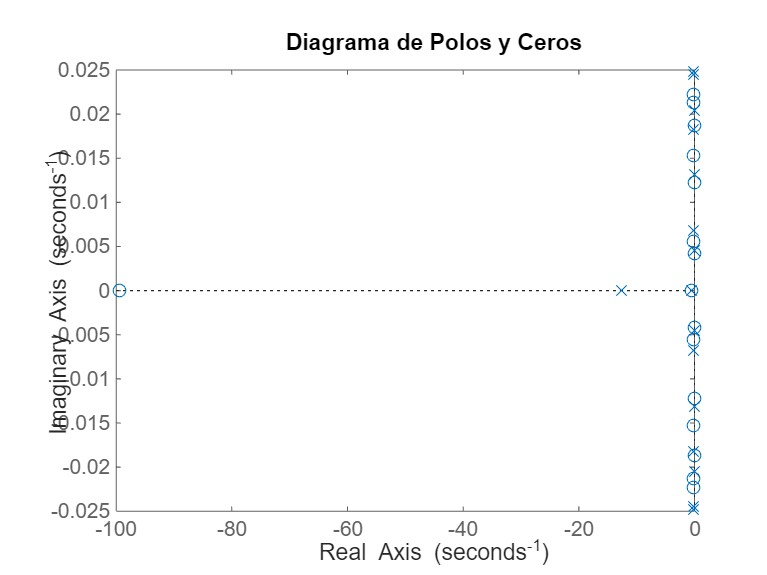

pzmap(G_PID);
title('Diagrama de Polos y Ceros');

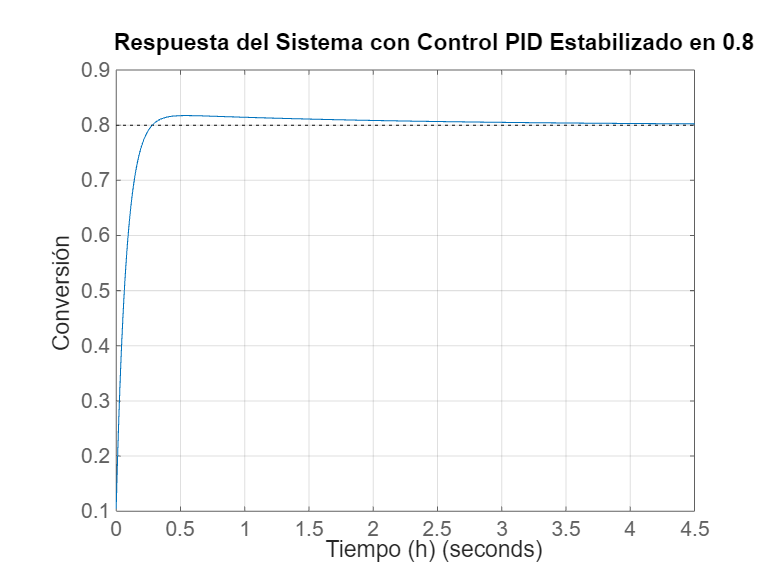


% Respuesta del sistema en lazo cerrado
y_target = 0.8; % Objetivo de estabilización
figure;
step(y_target * G_PID);
title('Respuesta del Sistema con Control PID Estabilizado en 0.8');
xlabel('Tiempo (h)'); ylabel('Conversión');
grid on;

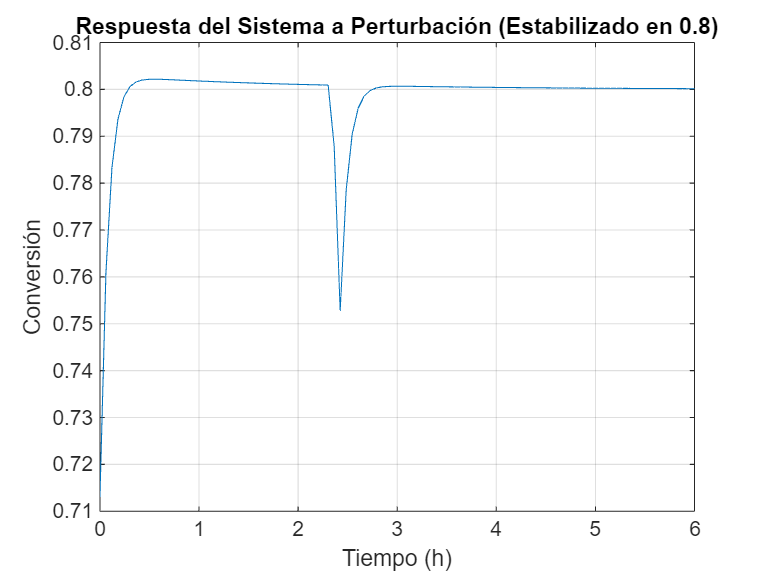


% Inserción de perturbación
t = linspace(0, 6, 100);
t_pert = t(40); % Tiempo en horas en que ocurre la perturbación
mag_pert = 0.1; % Magnitud de la perturbación
delta_u = zeros(size(t));
delta_u(t ~= t_pert) = mag_pert;

[y_pert, t_out] = lsim(G_PID, delta_u, t);

y_pert = y_pert - mag_pert;
figure;
plot(t_out, y_pert + y_target);
title('Respuesta del Sistema a Perturbación (Estabilizado en 0.8)');
xlabel('Tiempo (h)'); ylabel('Conversión');
grid on;